EE 451 Homework 6

Lisa Jacklin

%problem 2
%part a
N = 4; %given
%just so its easy for me to use, rather than i1, I will create j
j = sqrt(-1);

xn = [1 2 3 1]; %values given for x(n)
%from this, we can use the dftfunction we built in class to determine the
%Xk which can be converted back to xn using idft which will be graphed
%below.
Xk = fft(xn, N);
stem(Xk); %note that only the real parts are used

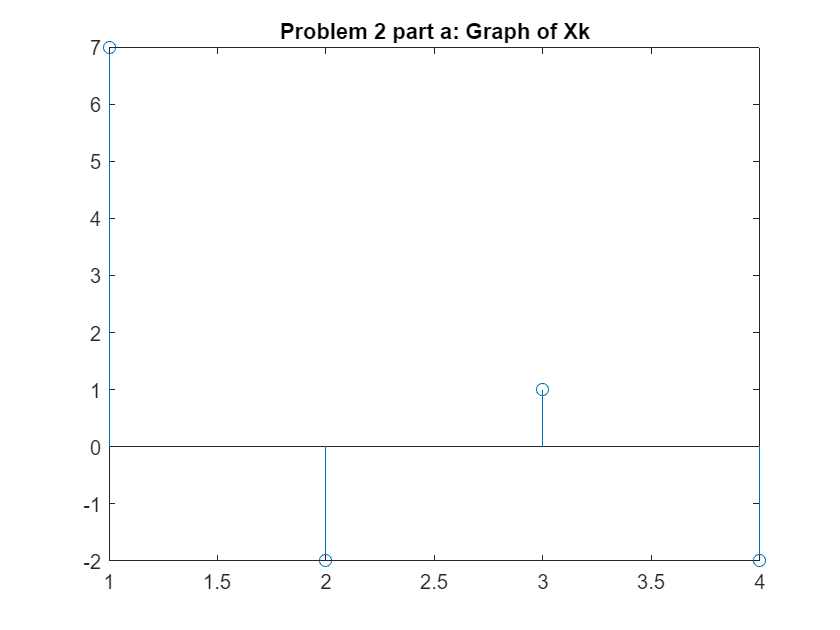

title("Problem 2 part a: Graph of Xk");

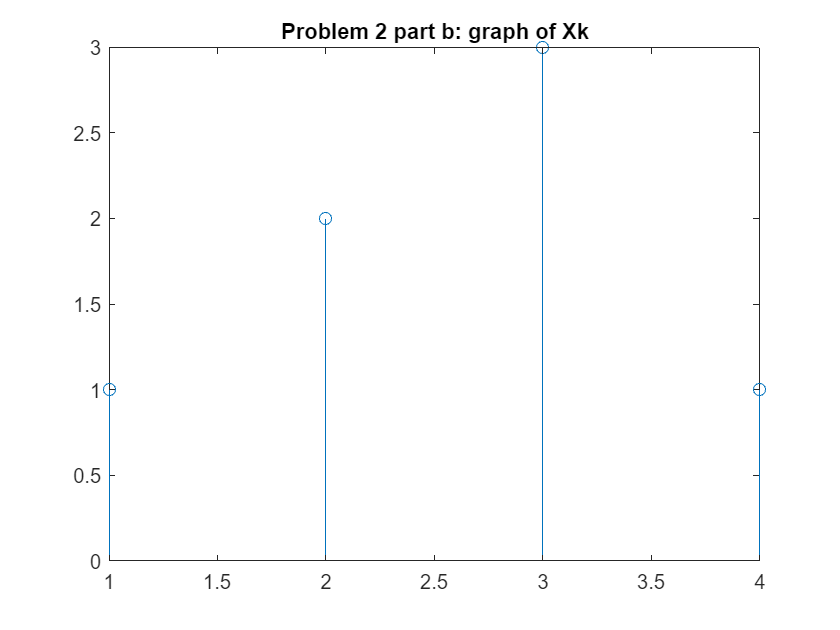

%Problem 2 part b

Xk2 = dft(xn, N);
stem(xn);
title("Problem 2 part b: graph of Xk");

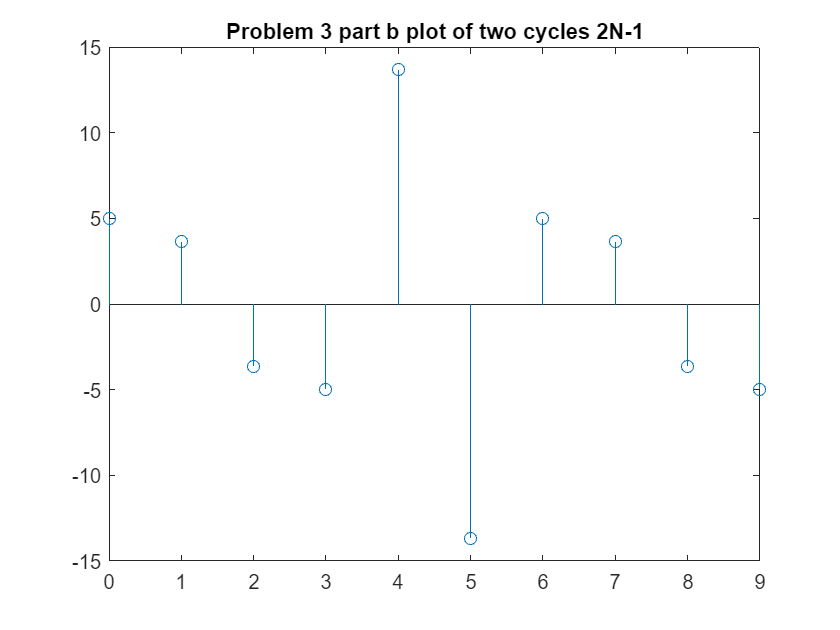


%Problem 3
%we are given the periodic equation x(n) = 5*cos(pi*n) + 10*sin((2*pi*n)/3)
%before we can do anything, we need to determine the period N of this
%function.

%problem 3 part a: What is N?
%since we are messing with cos and sin, an since sin has an admustment of
%2pi/3,but there is no adjustment to cos and since they are added together, we get 7pi/4ths....
N = 7*pi/4;

%with the value of N determined, we can finally begin to consider more
%about x(n).

%problem 3 part b: plot the signal for two cycles.
n = 0:1:2*N-1;
xpn = 5*cos(pi*n) + 10*sin((2*pi*n)/3);

stem(n, xpn);
title("Problem 3 part b plot of two cycles 2N-1")


%problem 3 part c: now we need to split x(n) into two sections to be
%considered, x1(n) which is over a single cycle and x2(n) which is
%considered over two cycles.

%once this is determined and plotted in terms of magnitude and phase, the
%2n point dft of x1 and x2 are determined and plotted as well.